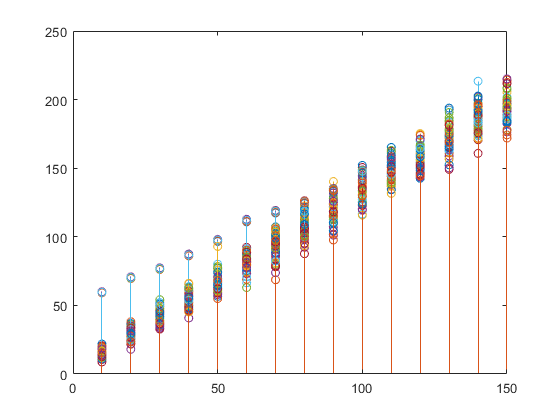

clear;
clc;
load('alphaData_4bit.mat');
figure();
dataDL=adc_VPVN;
dataDLMAcs=(reshape(dataDL,88,4,[])/0.9)*160;%MACs
MSB_powers=2.^[0 -1 -2 -3];
powerCombs=repmat(MSB_powers,72,1,15);
arrDL=[[1:18],8+[19:54],8+[55:72]];dataDLMAcs=dataDLMAcs(arrDL,:,:);
dataDLMAcs=dataDLMAcs.*powerCombs;
dataDLMAcs=sum(dataDLMAcs,2);
dataDLMAcs=reshape(dataDLMAcs,72,15,1);
dataDLMAcs=sum(dataDLMAcs,3);
dataDLMAcs=dataDLMAcs';
x_array = [10:10:150];
stem(x_array ,dataDLMAcs);

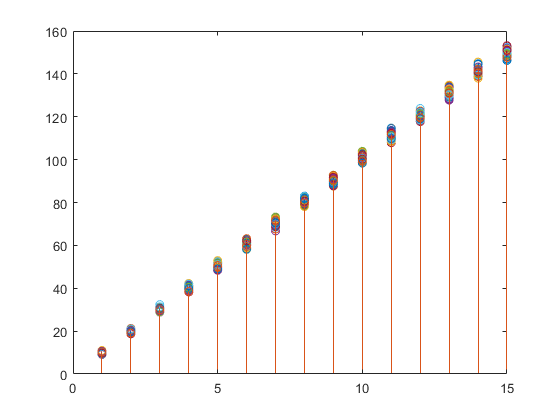




load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles_4Bit\dataWeights.mat')
load('dataCols.mat');
wtX=zeros(15,72,4);
for wt_MSBbits=0
    for colSel=0:3        
        data_DL =zeros(1092,88);
        data_DL  = [dataWeights(:,:,colSel+1+4*(wt_MSBbits));zeros(1092-1024,88)];
        data_DL=data_DL(:,arrDL);
        if(wt_MSBbits==0)
            wtX(:,:,colSel+1+4*(wt_MSBbits))=dataCols*data_DL*MSB_powers(colSel+1);
        else
            %wtX(:,:,colSel+1+4*(wt_MSBbits))=dataCols*data_DL*LSB_powers(colSel+1);
        end
    end
end
wtX=sum(wtX,3);
wtXBefore=wtX;
figure();
stem(wtX);

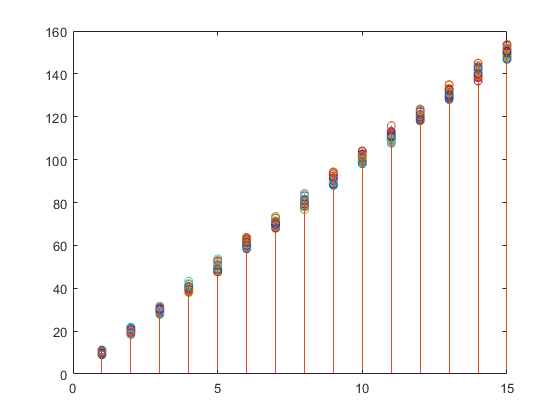


load('origAlphaData.mat')
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles_4Bit\dataWeights.mat')
load('dataCols.mat');
wtX=zeros(15,72,4);
wtSVolt=zeros(15,72,4);
alpha_DLs=[alpha_DLs;zeros(1092-1024,72)];
for wt_MSBbits=0
    for colSel=0:3        
        data_DL =zeros(1092,88);
        data_DL  = [dataWeights(:,:,colSel+1+4*(wt_MSBbits));zeros(1092-1024,88)];
        data_DL=data_DL(:,arrDL);
        data_DL=data_DL.*alpha_DLs;
        if(wt_MSBbits==0)
            wtX(:,:,colSel+1+4*(wt_MSBbits))=dataCols*data_DL*MSB_powers(colSel+1);
        else
            %wtX(:,:,colSel+1+4*(wt_MSBbits))=dataCols*data_DL*LSB_powers(colSel+1);
        end
        wtSVolt(:,:,colSel+1+4*(wt_MSBbits))=dataCols*data_DL*(0.9/160);
    end
end
wtX=sum(wtX,3);
wtXAfter=wtX;
figure();
stem(wtX);

figure();
powerS=repmat(reshape([MSB_powers],1,1,[]),15,72,1);
%powerS=repmat(reshape([MSB_powers,LSB_powers],1,1,[]),15,72,1);
%stem(sum(wtSVolt.*powerS*(160/0.9),3));


